Исходный текст:


HELLO WORLD THIS IS A TEST MESSAGE.


Исходные биты (первые 20):


     1     0     0     0     0     1     0     1     1     1     1     0     1     0     0     1     0     1     1     0



Закодированные биты (первые 20):


     1     1     1     0     1     1     1     1     0     0     1     0     0     1     0     0     1     0     1     0



Полученный текст:


HELLO WORLD THIS IS A TEST MESSAGE.


Вероятность битовой ошибки (BER): 0


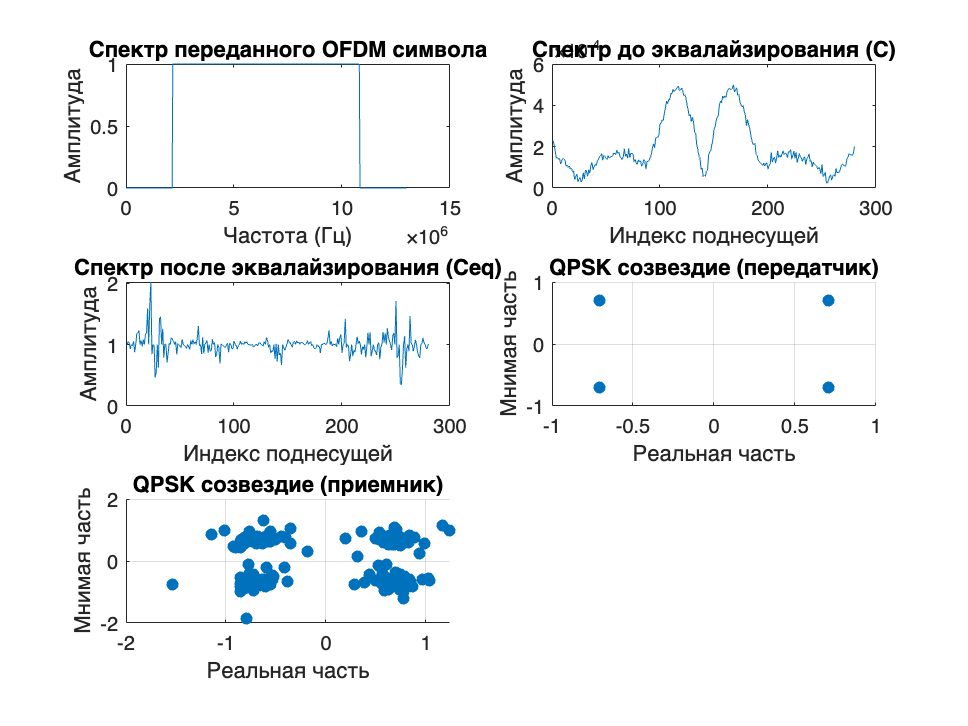

%% Полный цикл обработки сигнала в OFDM системе


clear all; clc;

%% Определение параметров модели
ofdm_params = ofdm_config();
channel_params = channel_config();

%% Генерация текстового сообщения
textMessage = 'HELLO WORLD THIS IS A TEST MESSAGE.';
disp('Исходный текст:');
disp(textMessage);

% Практика 1: Знаковое кодирование
bits = symbolEncoder(textMessage);
disp('Исходные биты (первые 20):');
disp(bits(1:min(20, end)));

% Практика 2: Сверточное кодирование
encoded_bits = convolutionalEncoder(bits);
disp('Закодированные биты (первые 20):');
disp(encoded_bits(1:min(20, end)));

% Практика 3: Перемежение
interleaved_bits = interleaver(encoded_bits);

% Практика 4: QPSK модуляция
qpsk_symbols = qpskModulator(interleaved_bits);

% Практика 5: OFDM модуляция
ofdm_symbol = ofdmModulator(qpsk_symbols, ofdm_params);

% Практика 6: Многолучевой канал
received_signal = multipathChannel(ofdm_symbol, channel_params);

% Практика 7: OFDM демодуляция
qpsk_symbols_rx = ofdmDemodulator(received_signal);

% Практика 8: QPSK демодуляция
received_interleaved_bits = qpskDemodulator(qpsk_symbols_rx);

% Практика 9: Обратное перемежение
received_encoded_bits = deinterleaver(received_interleaved_bits);

% Практика 10: Декодирование Витерби
decoded_bits = viterbiDecoder(received_encoded_bits);

% Практика 11: Знаковое декодирование
received_text = symbolDecoder(decoded_bits);
disp('Полученный текст:');
disp(received_text);

% Практика 12: Расчет BER
ber = calculateBER(bits, decoded_bits);
disp(['Вероятность битовой ошибки (BER): ', num2str(ber)]);

%% Построение графиков
figure('Name', 'Анализ сигналов');

% Спектр переданного OFDM символа
subplot(3, 2, 1);
ofdm_freq = fft(ofdm_symbol(getappdata(0, 'cpLength') + 1:end));
f = (0:length(ofdm_freq)-1) * (channel_params.bandwidth / length(ofdm_freq));
plot(f, abs(ofdm_freq));
title('Спектр переданного OFDM символа');
xlabel('Частота (Гц)');
ylabel('Амплитуда');

% Спектр принятого сигнала до эквалайзирования
C = getappdata(0, 'ofdmSpectrum_C');
subplot(3, 2, 2);
plot(1:length(C), abs(C));
title('Спектр до эквалайзирования (C)');
xlabel('Индекс поднесущей');
ylabel('Амплитуда');

% Спектр после эквалайзирования
Ceq = getappdata(0, 'equalizedSpectrum_Ceq');
subplot(3, 2, 3);
plot(1:length(Ceq), abs(Ceq));
title('Спектр после эквалайзирования (Ceq)');
xlabel('Индекс поднесущей');
ylabel('Амплитуда');

% QPSK созвездие в передатчике
subplot(3, 2, 4);
scatter(real(qpsk_symbols), imag(qpsk_symbols), 'filled');
title('QPSK созвездие (передатчик)');
xlabel('Реальная часть');
ylabel('Мнимая часть');
grid on;

% QPSK созвездие в приемнике
subplot(3, 2, 5);
scatter(real(qpsk_symbols_rx), imag(qpsk_symbols_rx), 'filled');
title('QPSK созвездие (приемник)');
xlabel('Реальная часть');
ylabel('Мнимая часть');
grid on;

set(gcf, 'Position', [100, 100, 800, 600]);

% function ofdmSymbol = ofdmModulator(qpskSymbols, params)
%     if ~isnumeric(qpskSymbols) || ~isvector(qpskSymbols)
%         error('[OFDM Modulator] Входные QPSK символы должны быть числовым вектором.');
%     end
%     if ~isstruct(params)
%         error('[OFDM Modulator] Параметры должны быть переданы в виде структуры.');
%     end
%     requiredFields = {'rsStep', 'cpLengthRatio', 'zeroPaddingRatio'};
%     for i = 1:length(requiredFields)
%         if ~isfield(params, requiredFields{i})
%             error('[OFDM Modulator] В структуре параметров отсутствует поле ''%s''.', requiredFields{i});
%         end
%     end
% 
%     Nqpsk = length(qpskSymbols);
%     rsStep = params.rsStep;
% 
%     if rsStep <= 1
%         error('[OFDM Modulator] rsStep должен быть больше 1.');
%     end
% 
%     Nrs_calc = ceil(Nqpsk / (rsStep - 1));
%     if Nqpsk == 0
%         Nrs_calc = 0;
%     end
% 
%     Nactive = Nqpsk + Nrs_calc;
% 
%     if Nactive > 0 && rsStep <= Nactive
%        rsIndices = 1:rsStep:Nactive;
%     else
%        rsIndices = [];
%     end
% 
%     Nrs = length(rsIndices);
%     Nactive = Nqpsk + Nrs;
% 
%     if ~isempty(rsIndices)
%        rsIndices = rsIndices(rsIndices <= Nactive);
%     end
% 
%     referenceSignal = (0.707 + 0.707j) * ones(1, Nrs);
% 
%     if Nactive > 0
%         allIndices = 1:Nactive;
%         dataIndices = setdiff(allIndices, rsIndices);
%     else
%         dataIndices = [];
%     end
% 
%     if length(dataIndices) ~= Nqpsk
%          error('[OFDM Modulator] Внутренняя ошибка: Несоответствие между индексами данных (%d) и Nqpsk (%d). Nactive=%d, Nrs=%d, rsStep=%d', ...
%                length(dataIndices), Nqpsk, Nactive, Nrs, rsStep);
%     end
% 
%      ofdmSpectrum = zeros(1, Nactive);
%      if Nrs > 0
%         ofdmSpectrum(rsIndices) = referenceSignal;
%      end
%      if Nqpsk > 0
%         ofdmSpectrum(dataIndices) = qpskSymbols;
%      end
% 
%     Nzero = round(params.zeroPaddingRatio * Nactive);
%     ofdmSpectrum = [zeros(1, Nzero), ofdmSpectrum, zeros(1, Nzero)];
%     timeDomainSignal = ifft(ofdmSpectrum);
% 
%     Nfft = length(timeDomainSignal);
%     cpLength = round(Nfft * params.cpLengthRatio);
%     cpLength = min(cpLength, Nfft);
% 
%     if cpLength > 0
%         cyclicPrefix = timeDomainSignal(end-cpLength+1:end);
%         ofdmSymbol = [cyclicPrefix, timeDomainSignal];
%     else
%         ofdmSymbol = timeDomainSignal;
%     end
% 
%     setappdata(0, 'referenceSignal', referenceSignal);
%     setappdata(0, 'rsIndices', rsIndices);
%     setappdata(0, 'Nzero', Nzero);
%     setappdata(0, 'Nrs', Nrs);
%     setappdata(0, 'Nqpsk', Nqpsk);
%     setappdata(0, 'cpLength', cpLength);
%     setappdata(0, 'Nactive', Nactive);
% end
% 
% function modulatedSymbols = qpskModulator(inputBits)
%     if ~isnumeric(inputBits) || ~isvector(inputBits) || any((inputBits ~= 0) & (inputBits ~= 1))
%         error('[QPSK Modulator] Входные биты должны быть числовым вектором, содержащим только 0 и 1.');
%     end
% 
%     if mod(length(inputBits), 2) ~= 0
%         warning('[QPSK Modulator] Длина входной битовой последовательности нечетная. Добавляем 0 в конец.');
%         inputBits = [inputBits, 0]; 
%     end
% 
%     numSymbols = length(inputBits) / 2;
%     modulatedSymbols = zeros(1, numSymbols);
%     for i = 1:numSymbols
%         bit1 = inputBits(2*i-1);
%         bit2 = inputBits(2*i);
% 
%        if bit1 == 0 && bit2 == 0
%             modulatedSymbols(i) = 0.707 + 0.707j;
%         elseif bit1 == 0 && bit2 == 1
%             modulatedSymbols(i) = 0.707 - 0.707j;
%         elseif bit1 == 1 && bit2 == 0
%             modulatedSymbols(i) = -0.707 + 0.707j;
%         elseif bit1 == 1 && bit2 == 1
%             modulatedSymbols(i) = -0.707 - 0.707j;
%        end
%     end
% end
% 
% function encodedBits = convolutionalEncoder(inputBits)
%     if ~isnumeric(inputBits) || ~isvector(inputBits) || any((inputBits ~= 0) & (inputBits ~= 1))
%         error('[ConvolutionalEncoder] Входные биты должны быть числовым вектором, содержащим только 0 и 1.');
%     end 
% 
%     [constraintLength, codeGenerator] = getCodingParameters();
%     trellis = poly2trellis(constraintLength, codeGenerator);
%     encodedBits = convenc(inputBits, trellis);
% end
% 
% function encodedBits = symbolEncoder(message)
%     [alphabet, bitsPerSymbol] = getAlphabet();
% 
%     if ~ischar(message) || ~isvector(message)
%         error('[SymbolEncoder] Входное сообщение на должно быть вектором символов.');
%     end
% 
%     encodedBits = [];
%     for i = 1:length(message)
%         alphabetCharIndex = find(alphabet == message(i));
% 
%         if isempty(alphabetCharIndex)
%             error('[SymbolEncoder] Символ %s отсутствует в алфавите.', message(i));
%         end
% 
%     decimalValue = alphabetCharIndex(1) - 1;
%     binaryValue = de2bi(decimalValue, bitsPerSymbol, 'left-msb');
%     encodedBits = [encodedBits, binaryValue];
%     end
% end
% 
% function interleavedBits = interleaver(inputBits)
%     if ~isnumeric(inputBits) || ~isvector(inputBits) || any((inputBits ~= 0) & (inputBits ~=1))
%         error('[Interleaver] Входные биты должны быть числовым вектором, содержащим только 0 и 1.');
%     end
% 
%     permutationVector = randperm(length(inputBits));
%     interleavedBits = inputBits(permutationVector);
% 
%     setappdata(0, 'permutationVector', permutationVector);
% end
% 
% function [alphabet, bitsPerSymbol] = getAlphabet()
%     alphabet = ['a':'z', 'A':'Z', '0':'9', ' ', '.'];
%     bitsPerSymbol = ceil(log2(length(alphabet)));
% end
% 
% function params = channel_config()
%     params.numRays = 7;
%     params.noisePowerBW = -120;
%     params.bandwidth = 13e6;
%     params.carrierFrequency = 1.9e9;
%     params.c = 3e8;
% end
% 
% function params = ofdm_config()
%     params.rsStep = 4;
%     params.cpLengthRatio = 1/8;
%     params.zeroPaddingRatio = 1/4;
% end
% 
% function [constraintLength, codeGenerator] = getCodingParameters()
%     constraintLength = 7;
%     codeGenerator = [171, 133];
% end
% 
% function receivedSignal = multipathChannel(transmittedSignal, params)
%     if ~isnumeric(transmittedSignal) || ~isvector(transmittedSignal)
%         error('[Multipath Channel] Переданный сигнал должен быть числовым вектором.');
%     end
%     if ~isstruct(params)
%         error('[Multipath Channel] Параметры канала должны быть переданы в виде структуры.');
%     end
%     requiredFields = {'numRays', 'noisePowerBW', 'bandwidth', 'carrierFrequency', 'c'};
%     for i = 1:length(requiredFields)
%         if ~isfield(params, requiredFields{i})
%             error('[Multipath Channel] В структуре параметров отсутствует поле ''%s''.', requiredFields{i});
%         end
%     end
% 
%     L = length(transmittedSignal);
%     Ts = 1/params.bandwidth;
%     D = randi([10,500], 1, params.numRays);
% 
%     [Dmin, ~] = min(D);
%     tau_sec = (D - Dmin) / params.c;
%     tau_samples = round(tau_sec / Ts);
%     G = params.c ./ (4 * pi * D * params.carrierFrequency);
%     max_tau = max(tau_samples);
%     delayedSignals = zeros(params.numRays, L + max_tau);
% 
%     for i = 1:params.numRays
%         startIndex = tau_samples(i) + 1;
%         endIndex = tau_samples(i) + L;
%         delayedSignals(i, startIndex:endIndex) = transmittedSignal * G(i);
%     end
% 
%     multipathChannel = sum(delayedSignals, 1);
%     noise = wgn(1, length(multipathChannel), params.noisePowerBW, 'complex');
%     receivedSignal = multipathChannel + noise;
% end
% 
% function demodulatedBits = qpskDemodulator(receivedSymbols)
%     if ~isnumeric(receivedSymbols) || ~isvector(receivedSymbols)
%         error('[QPSK Demodulator] Входные символы должны быть числовым вектором.');
%     end
% 
%     numSymbols = length(receivedSymbols);
%     demodulatedBits = zeros(1, 2 * numSymbols);
% 
%     for i = 1:numSymbols
%         realPart = real(receivedSymbols(i));
%         imagPart = imag(receivedSymbols(i));
% 
%         if realPart >= 0 && imagPart >= 0
%             demodulatedBits(2*i-1:2*i) = [0 0];
%         elseif realPart >= 0 && imagPart < 0
%             demodulatedBits(2*i-1:2*i) = [0 1];
%         elseif realPart < 0 && imagPart >= 0
%             demodulatedBits(2*i-1:2*i) = [1 0];
%         elseif realPart < 0 && imagPart < 0
%             demodulatedBits(2*i-1:2*i) = [1 1];
%         end
%     end
% end
% 
% function decodedMessage = symbolDecoder(encodedBits)
%     [alphabet, bitsPerSymbol] = getAlphabet();
% 
%     if ~isnumeric(encodedBits) || ~isvector(encodedBits) || any((encodedBits ~= 0) & (encodedBits ~= 1))
%         error('[SymbolDecoder] Входные биты должны быть числовым вектором, содержащим только 0 и 1.');
%     end
% 
%     numSymbols = length(encodedBits)/bitsPerSymbol;
%     if rem(length(encodedBits), bitsPerSymbol) ~= 0
%         warning('[SymbolDecoder] Длина входной битовой последовательности не кратна количеству бит на символ. Лишние биты будут проигнорированы.');
%         numSymbols = floor(numSymbols);
%     end
% 
%     decodedMessage = '';
%     for i = 1:numSymbols
%         symbolBits = encodedBits((i-1)*bitsPerSymbol+1 : i*bitsPerSymbol);
%         decimalValue = bi2de(symbolBits, 'left-msb');
%         alphabetCharIndex = decimalValue + 1;
% 
%         if alphabetCharIndex > 0 && alphabetCharIndex <= length(alphabet)
%             decodedMessage = [decodedMessage, alphabet(alphabetCharIndex)];
%         else
%             decodedMessage = [decodedMessage, '?'];
%         end
%     end 
% end
% 
% function deinterleavedBits = deinterleaver(inputBits)
%     if ~isnumeric(inputBits) || ~isvector(inputBits) || any((inputBits ~= 0) & (inputBits ~= 1))
%            error('[Deinterleaver] Входные биты должны быть числовым вектором, содержащим только 0 и 1.');
%     end
% 
%     permutationVector = getappdata(0, 'permutationVector');
% 
%     if isempty(permutationVector)
%         error('[Deinterleaver] Вектор перестановки не был сохранен. Убедитесь, что прямой перемежитель был выполнен.');
%     end
% 
%     deinterleavedBits = zeros(size(inputBits));
%     deinterleavedBits(permutationVector) = inputBits;
% end
% 
% function decodedBits = viterbiDecoder(encodedBits)
%     [constraintLength, codeGenerator] = getCodingParameters();
%     trellis = poly2trellis(constraintLength, codeGenerator);
% 
%     if ~isnumeric(encodedBits) || ~isvector(encodedBits) || any((encodedBits ~= 0) & (encodedBits ~= 1))
%         error('[ViterbiDecoder] Входные биты должны быть числовым вектором, содержащим только 0 и 1.');
%     end
% 
%     tbLen = 5 * constraintLength;
%     decodedBits = vitdec(encodedBits, trellis, tbLen, 'trunc', 'hard');
% end
% 
% function qpskSymbolsOut = ofdmDemodulator(receivedSignal)
%     cpLength = getappdata(0, 'cpLength');
%     Nzero = getappdata(0, 'Nzero');
%     rsIndices = getappdata(0, 'rsIndices');
%     referenceSignal = getappdata(0, 'referenceSignal');
%     Nqpsk = getappdata(0, 'Nqpsk');
%     Nrs = getappdata(0, 'Nrs');
% 
%     if isempty(cpLength) || isempty(Nzero) || isempty(rsIndices) || isempty(referenceSignal) || isempty(Nqpsk) || isempty(Nrs)
%          error('[OFDM Demodulator] Не удалось получить параметры, сохраненные модулятором. Убедитесь, что ofdmModulator был выполнен.');
%     end
% 
%     if ~isnumeric(receivedSignal) || ~isvector(receivedSignal)
%         error('[OFDM Demodulator] Принятый сигнал должен быть числовым вектором.');
%     end
%     expectedMinLength = cpLength + Nqpsk + Nrs + 2*Nzero;
% 
%     signalLength = length(receivedSignal);
%     if signalLength > expectedMinLength
%         cpPart = receivedSignal(1:cpLength);
%         corr = zeros(1, signalLength - cpLength + 1);
%         for i = 1:length(corr)
%             corr(i) = abs(sum(conj(cpPart) .* receivedSignal(i:i+cpLength-1)));
%         end
%         [~, startIdx] = max(corr);
%         receivedSignal = receivedSignal(startIdx:startIdx+expectedMinLength-1);
%     end
% 
%     if length(receivedSignal) ~= expectedMinLength
%         warning('[OFDM Demodulator] Длина принятого сигнала (%d) не совпадает с ожидаемой (%d).', length(receivedSignal), expectedMinLength);
%     end
% 
%     signalWithoutCP = receivedSignal(cpLength+1:end);
%     ofdmSpectrum = fft(signalWithoutCP);
%     C = ofdmSpectrum(Nzero+1:end-Nzero);
% 
%     if length(C) ~= (Nqpsk + Nrs)
%          error('[OFDM Demodulator] Размер спектра активных поднесущих (%d) не совпадает с ожидаемым (%d).', length(C), Nqpsk + Nrs);
%     end
% 
%     receivedReferenceSignal = C(rsIndices);
%     H = receivedReferenceSignal ./ referenceSignal;
%     indicesAll = 1:length(C);
%     H_interpolated = interp1(rsIndices, H, indicesAll, 'spline');
% 
%     epsilon = 1e-10;
%     Ceq = C ./ (H_interpolated + epsilon);
% 
%     dataIndices = setdiff(indicesAll, rsIndices);
%     qpskSymbolsOut = Ceq(dataIndices);
% 
%     setappdata(0, 'ofdmSpectrum_C', C);
%     setappdata(0, 'channelEstimate_H_interp', H_interpolated);
%     setappdata(0, 'equalizedSpectrum_Ceq', Ceq);
% end
% 
% function ber = calculateBER(originalBits, decodedBits)
%     minLength = min(length(originalBits), length(decodedBits));
%     ber = sum(originalBits(1:minLength) ~= decodedBits(1:minLength)) / minLength;
% end